# Robotics 2 - Final exam, February 5, 2018

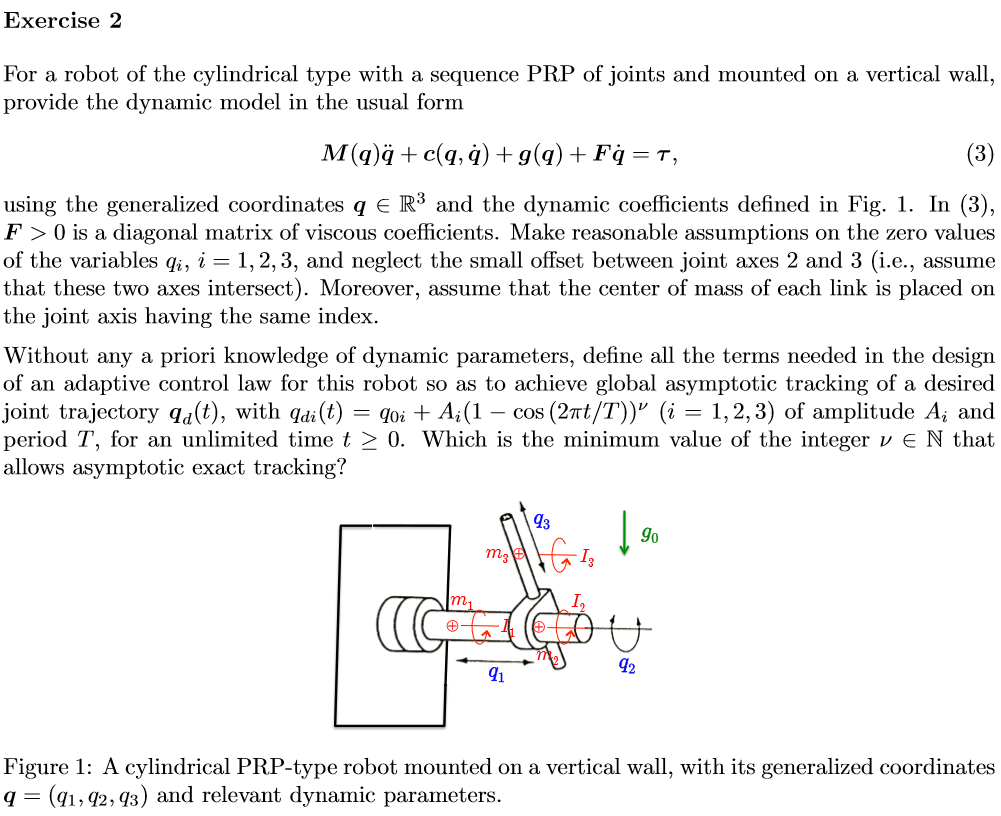

clear; clc;
sigma = [1,0,1]; %PRP
n= length(sigma)

n = 3

q = sym('q',[n 1]);
qd = sym('qd',[n 1]);
qdd = sym('qdd',[n 1]);
l = sym('l',[n 1]);
m = sym('m',[n 1]);
d = sym('d',[n 1]);
I = sym('I',[n 1]);
g = sym('g')

$$g = g$$

g0 = [0 g 0].'

$$g0 = \left(\begin{array}{c} 0\\ g\\ 0 \end{array}\right)$$

F = diag(sym('f',[n,1]));
dhTable = [0    0 q(1) 0;
           -pi/2 0 0 q(2);
           0 0 q(3)-d(3) 0]

$$dhTable = \left(\begin{array}{cccc} 0 & 0 & q_{1} & 0\\ -\frac{\pi }{2} & 0 & 0 & q_{2}\\ 0 & 0 & q_{3}-d_{3} & 0 \end{array}\right)$$

%l = [q(1) 0 q(3)]
%dc = [q(1) - di(1), di(2), q(3)-di(3)]

[KE, T] = getKEwithJacobian(dhTable,sigma,q,qd,l,m,I,d,0)

*** Computation of Kinetic Energy (Jacobian-based method) 


$$KE = \frac{I_{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{I_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{3}}^{2}}{2}+\frac{{d_{3}}^{2}\,m_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{3}\,{q_{3}}^{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}-d_{3}\,m_{3}\,q_{3}\,{{\mathrm{qd}}_{2}}^{2}$$

T = 1×3 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}


for i=1:n
    T{i}
end

$$ans = \frac{m_{1}\,{{\mathrm{qd}}_{1}}^{2}}{2}$$

$$ans = \frac{m_{2}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{I_{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}$$

$$ans = \frac{m_{3}\,{d_{3}}^{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}-m_{3}\,d_{3}\,q_{3}\,{{\mathrm{qd}}_{2}}^{2}+\frac{m_{3}\,{q_{3}}^{2}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{1}}^{2}}{2}+\frac{I_{3}\,{{\mathrm{qd}}_{2}}^{2}}{2}+\frac{m_{3}\,{{\mathrm{qd}}_{3}}^{2}}{2}$$

M = getInertiaMatrixFromKE(KE,qd)

$$M = \left(\begin{array}{ccc} m_{1}+m_{2}+m_{3} & 0 & 0\\ 0 & m_{3}\,{d_{3}}^{2}-2\,m_{3}\,d_{3}\,q_{3}+m_{3}\,{q_{3}}^{2}+I_{2}+I_{3} & 0\\ 0 & 0 & m_{3} \end{array}\right)$$

[c,S] = getcS(M,q,qd)

============= Link 1
============= Link 2
============= Link 3


$$c = \left(\begin{array}{c} 0\\ -2\,m_{3}\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3}\,\left(d_{3}-q_{3}\right)\\ m_{3}\,{{\mathrm{qd}}_{2}}^{2}\,\left(d_{3}-q_{3}\right) \end{array}\right)$$

$$S = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & -m_{3}\,{\mathrm{qd}}_{3}\,\left(d_{3}-q_{3}\right) & -m_{3}\,{\mathrm{qd}}_{2}\,\left(d_{3}-q_{3}\right)\\ 0 & m_{3}\,{\mathrm{qd}}_{2}\,\left(d_{3}-q_{3}\right) & 0 \end{array}\right)$$

g_q = getGravityWithJacobian(dhTable,q,l,m,d,g0,0)

*** Computation of Potential Energy (Jacobian-based method) 


$$g\_q = \left(\begin{array}{c} 0\\ g\,m_{3}\,\sin\left(q_{2}\right)\,\left(d_{3}-q_{3}\right)\\ g\,m_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$

torque = M*qdd + c + g_q +F*qd

$$torque = \left(\begin{array}{c} f_{1}\,{\mathrm{qd}}_{1}+{\mathrm{qdd}}_{1}\,\left(m_{1}+m_{2}+m_{3}\right)\\ f_{2}\,{\mathrm{qd}}_{2}+{\mathrm{qdd}}_{2}\,\left(m_{3}\,{d_{3}}^{2}-2\,m_{3}\,d_{3}\,q_{3}+m_{3}\,{q_{3}}^{2}+I_{2}+I_{3}\right)-2\,m_{3}\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3}\,\left(d_{3}-q_{3}\right)+g\,m_{3}\,\sin\left(q_{2}\right)\,\left(d_{3}-q_{3}\right)\\ m_{3}\,\left(d_{3}-q_{3}\right)\,{{\mathrm{qd}}_{2}}^{2}+f_{3}\,{\mathrm{qd}}_{3}+m_{3}\,{\mathrm{qdd}}_{3}+g\,m_{3}\,\cos\left(q_{2}\right) \end{array}\right)$$

[All, dynamicParamsReturn, a]= getDynamicParameters2([M,S,diag(g_q),F],q,[qd.',g])

>> Getting dynamic coefficients. Might take a while...


params1term = 1×7 logical array
   0   1   1   1   1   1   1


MSubs First iteration


$$Msubs = \left(\begin{array}{cccccccccccc} {\mathrm{aa}}_{1} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & {\mathrm{aa}}_{3} & 0 & 0\\ 0 & {\mathrm{aa}}_{5}\,{q_{3}}^{2}-2\,{\mathrm{aa}}_{2}\,q_{3}+I_{2}+I_{3}+{\mathrm{aa}}_{2}\,d_{3} & 0 & 0 & {\mathrm{aa}}_{5}\,q_{3}\,{\mathrm{qd}}_{3}-{\mathrm{aa}}_{2}\,{\mathrm{qd}}_{3} & {\mathrm{aa}}_{5}\,q_{3}\,{\mathrm{qd}}_{2}-{\mathrm{aa}}_{2}\,{\mathrm{qd}}_{2} & 0 & {\mathrm{aa}}_{2}\,g\,\sin\left(q_{2}\right)-{\mathrm{aa}}_{5}\,g\,q_{3}\,\sin\left(q_{2}\right) & 0 & 0 & {\mathrm{aa}}_{4} & 0\\ 0 & 0 & {\mathrm{aa}}_{5} & 0 & {\mathrm{aa}}_{2}\,{\mathrm{qd}}_{2}-{\mathrm{aa}}_{5}\,q_{3}\,{\mathrm{qd}}_{2} & 0 & 0 & 0 & {\mathrm{aa}}_{5}\,g\,\cos\left(q_{2}\right) & 0 & 0 & {\mathrm{aa}}_{6} \end{array}\right)$$

MSubs second iteration (before re-replacement)


$$Msubs = \left(\begin{array}{cccccccccccc} {\mathrm{aa}}_{1} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & {\mathrm{aa}}_{3} & 0 & 0\\ 0 & {\mathrm{aa}}_{5}\,{q_{3}}^{2}-2\,{\mathrm{aa}}_{2}\,q_{3}+{\mathrm{aa}}_{8} & 0 & 0 & {\mathrm{aa}}_{5}\,q_{3}\,{\mathrm{qd}}_{3}-{\mathrm{aa}}_{2}\,{\mathrm{qd}}_{3} & {\mathrm{aa}}_{5}\,q_{3}\,{\mathrm{qd}}_{2}-{\mathrm{aa}}_{2}\,{\mathrm{qd}}_{2} & 0 & {\mathrm{aa}}_{2}\,g\,\sin\left(q_{2}\right)-{\mathrm{aa}}_{5}\,g\,q_{3}\,\sin\left(q_{2}\right) & 0 & 0 & {\mathrm{aa}}_{4} & 0\\ 0 & 0 & {\mathrm{aa}}_{5} & 0 & {\mathrm{aa}}_{2}\,{\mathrm{qd}}_{2}-{\mathrm{aa}}_{5}\,q_{3}\,{\mathrm{qd}}_{2} & 0 & 0 & 0 & {\mathrm{aa}}_{5}\,g\,\cos\left(q_{2}\right) & 0 & 0 & {\mathrm{aa}}_{6} \end{array}\right)$$

$$Msubs = \begin{array}{l} \left(\begin{array}{cccccccccccc} a_{1} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & a_{3} & 0 & 0\\ 0 & a_{5}\,{q_{3}}^{2}-2\,a_{2}\,q_{3}+a_{7} & 0 & 0 & -{\mathrm{qd}}_{3}\,\left(a_{2}-a_{5}\,q_{3}\right) & -\sigma_{1} & 0 & g\,\sin\left(q_{2}\right)\,\left(a_{2}-a_{5}\,q_{3}\right) & 0 & 0 & a_{4} & 0\\ 0 & 0 & a_{5} & 0 & \sigma_{1} & 0 & 0 & 0 & a_{5}\,g\,\cos\left(q_{2}\right) & 0 & 0 & a_{6} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{qd}}_{2}\,\left(a_{2}-a_{5}\,q_{3}\right) \end{array}$$

$$All = \begin{array}{l} \left(\begin{array}{cccccccccccc} a_{1} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & a_{3} & 0 & 0\\ 0 & a_{5}\,{q_{3}}^{2}-2\,a_{2}\,q_{3}+a_{7} & 0 & 0 & -{\mathrm{qd}}_{3}\,\left(a_{2}-a_{5}\,q_{3}\right) & -\sigma_{1} & 0 & g\,\sin\left(q_{2}\right)\,\left(a_{2}-a_{5}\,q_{3}\right) & 0 & 0 & a_{4} & 0\\ 0 & 0 & a_{5} & 0 & \sigma_{1} & 0 & 0 & 0 & a_{5}\,g\,\cos\left(q_{2}\right) & 0 & 0 & a_{6} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{qd}}_{2}\,\left(a_{2}-a_{5}\,q_{3}\right) \end{array}$$

$$dynamicParamsReturn = \left(\begin{array}{c} m_{1}+m_{2}+m_{3}\\ d_{3}\,m_{3}\\ f_{1}\\ f_{2}\\ m_{3}\\ f_{3}\\ m_{3}\,{d_{3}}^{2}+I_{2}+I_{3} \end{array}\right)$$

$$a = \left(\begin{array}{ccccccc} a_{1} & a_{2} & a_{3} & a_{4} & a_{5} & a_{6} & a_{7} \end{array}\right)$$

[M,S,diag(g_q),F]

$$ans = \begin{array}{l} \left(\begin{array}{cccccccccccc} m_{1}+m_{2}+m_{3} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & f_{1} & 0 & 0\\ 0 & m_{3}\,{d_{3}}^{2}-2\,m_{3}\,d_{3}\,q_{3}+m_{3}\,{q_{3}}^{2}+I_{2}+I_{3} & 0 & 0 & -m_{3}\,{\mathrm{qd}}_{3}\,\left(d_{3}-q_{3}\right) & -\sigma_{1} & 0 & g\,m_{3}\,\sin\left(q_{2}\right)\,\left(d_{3}-q_{3}\right) & 0 & 0 & f_{2} & 0\\ 0 & 0 & m_{3} & 0 & \sigma_{1} & 0 & 0 & 0 & g\,m_{3}\,\cos\left(q_{2}\right) & 0 & 0 & f_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{3}\,{\mathrm{qd}}_{2}\,\left(d_{3}-q_{3}\right) \end{array}$$

a_order = a([1,7,2,5,3,4,6])

$$a\_order = \left(\begin{array}{ccccccc} a_{1} & a_{7} & a_{2} & a_{5} & a_{3} & a_{4} & a_{6} \end{array}\right)$$

Msubs = All(:,1:3)

$$Msubs = \left(\begin{array}{ccc} a_{1} & 0 & 0\\ 0 & a_{5}\,{q_{3}}^{2}-2\,a_{2}\,q_{3}+a_{7} & 0\\ 0 & 0 & a_{5} \end{array}\right)$$

Ssubs = All(:,4:6)

$$Ssubs = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & -{\mathrm{qd}}_{3}\,\left(a_{2}-a_{5}\,q_{3}\right) & -{\mathrm{qd}}_{2}\,\left(a_{2}-a_{5}\,q_{3}\right)\\ 0 & {\mathrm{qd}}_{2}\,\left(a_{2}-a_{5}\,q_{3}\right) & 0 \end{array}\right)$$

gSubs = diag(All(:,7:9))

$$gSubs = \left(\begin{array}{c} 0\\ g\,\sin\left(q_{2}\right)\,\left(a_{2}-a_{5}\,q_{3}\right)\\ a_{5}\,g\,\cos\left(q_{2}\right) \end{array}\right)$$

FSubs = All(:,10:12)

$$FSubs = \left(\begin{array}{cccc} 0 & a_{3} & 0 & 0\\ 0 & 0 & a_{4} & 0\\ a_{5}\,g\,\cos\left(q_{2}\right) & 0 & 0 & a_{6} \end{array}\right)$$

torqueSubs = Msubs*qdd + Ssubs*qd + gSubs +FSubs*qd

$$torqueSubs = \left(\begin{array}{c} a_{3}\,{\mathrm{qd}}_{1}+a_{1}\,{\mathrm{qdd}}_{1}\\ a_{4}\,{\mathrm{qd}}_{2}+{\mathrm{qdd}}_{2}\,\left(a_{5}\,{q_{3}}^{2}-2\,a_{2}\,q_{3}+a_{7}\right)-2\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3}\,\left(a_{2}-a_{5}\,q_{3}\right)+g\,\sin\left(q_{2}\right)\,\left(a_{2}-a_{5}\,q_{3}\right)\\ \left(a_{2}-a_{5}\,q_{3}\right)\,{{\mathrm{qd}}_{2}}^{2}+a_{6}\,{\mathrm{qd}}_{3}+a_{5}\,{\mathrm{qdd}}_{3}+a_{5}\,g\,\cos\left(q_{2}\right) \end{array}\right)$$

$$dynamicParamsReturn = \left(\begin{array}{c} m_{1}+m_{2}+m_{3}\\ d_{3}\,m_{3}\\ f_{1}\\ f_{2}\\ m_{3}\\ f_{3}\\ m_{3}\,{d_{3}}^{2}+I_{2}+I_{3} \end{array}\right)$$

$$ans = \left(\begin{array}{c} m_{1}+m_{2}+m_{3}\\ m_{3}\,{d_{3}}^{2}+I_{2}+I_{3}\\ d_{3}\,m_{3}\\ m_{3}\\ f_{1}\\ f_{2}\\ f_{3} \end{array}\right)$$

getLinearParametrization(torqueSubs,a_order)

$$ans = \left(\begin{array}{ccccccc} {\mathrm{qdd}}_{1} & 0 & 0 & 0 & {\mathrm{qd}}_{1} & 0 & 0\\ 0 & {\mathrm{qdd}}_{2} & g\,\sin\left(q_{2}\right)-2\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3}-2\,q_{3}\,{\mathrm{qdd}}_{2} & {q_{3}}^{2}\,{\mathrm{qdd}}_{2}-g\,q_{3}\,\sin\left(q_{2}\right)+2\,q_{3}\,{\mathrm{qd}}_{2}\,{\mathrm{qd}}_{3} & 0 & {\mathrm{qd}}_{2} & 0\\ 0 & 0 & {{\mathrm{qd}}_{2}}^{2} & -q_{3}\,{{\mathrm{qd}}_{2}}^{2}+{\mathrm{qdd}}_{3}+g\,\cos\left(q_{2}\right) & 0 & 0 & {\mathrm{qd}}_{3} \end{array}\right)$$